# How to build a Run Tracker with MATLAB

## Background story

We use MATLAB Mobile to collect acceleration and position data from an [Android](https://www.mathworks.com/help/matlabmobile_android/sensor-data-collection.html)™ or [iOS](https://www.mathworks.com/help/matlabmobile/sensor-data-collection.html) mobile device and use it to build a run/walk tracker.

### Goals

For the short demo today, we will use the sensor data to count the number of steps taken and map the course taken.

### Steps

We will do the following:

- Import data

- Interactively visualize and explore trends

- Process raw data to count steps 

- Create a web map of the course

- Document results

## 0. Add workshop folder to path

In order for any of the workshop files to work, we need to add all working folders and sub-folders to path.

addpath('/MATLAB Drive/RunTracker')

## 1. Importing data

Collect data from MATLAB Mobile as described [here for iOS](https://www.mathworks.com/help/matlabmobile/ug/sensor-data-collection-with-matlab-mobile.html) and [here for Android](https://www.mathworks.com/help/matlabmobile_android/ug/sensor-data-collection-with-matlab-mobile.html). The data file will be available in MATLAB Drive: 

*C:\Users\<username>\Documents\MATLABDrive\MobileSensorData   *

Copy and paste that file into the working folder.

load workshop_sensorlog_20201117_125104.mat

Let's look at how the data is stored in MATLAB. 

First, we explore acceleration data.

%% Add your code here
Acceleration.Properties

ans =   TimetableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Timestamp'  'Variables'}
           VariableNames: {'X'  'Y'  'Z'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowTimes: [23652x1 datetime]
               StartTime: 17-Nov-2020 12:51:04.531
              SampleRate: NaN
                TimeStep: NaN
                  Events: []
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


T = Acceleration.Timestamp;
Ax = Acceleration.X;
Ay = Acceleration.Y;
Az = Acceleration.Z;


Now lets look at position data.

Position.Properties

ans =   TimetableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Timestamp'  'Variables'}
           VariableNames: {'latitude'  'longitude'  'altitude'  'speed'  'course'  'hacc'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowTimes: [2379x1 datetime]
               StartTime: 17-Nov-2020 12:51:04.995
              SampleRate: NaN
                TimeStep: NaN
                  Events: []
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


## 2. Visualize data

There are multiple ways to plot data. You can use the [plot](https://www.mathworks.com/help/matlab/ref/plot.html) function, or you can use the following ways.

## 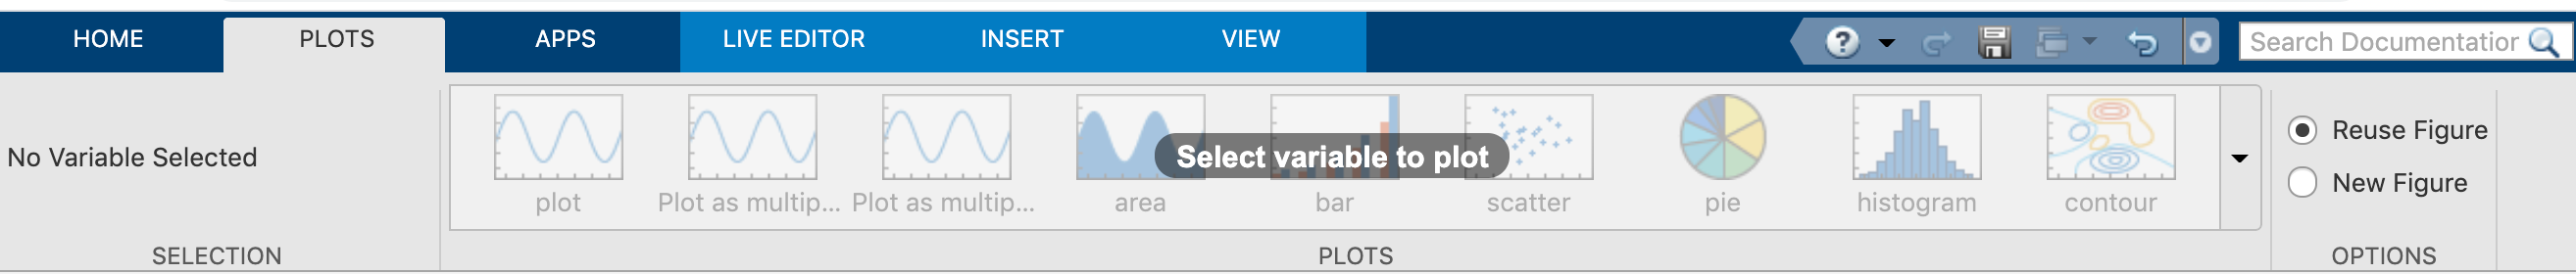

- Select the variables **T** and **[Ax Ay Az]** from the workspace using Ctrl+Left Click

- In the **PLOTS** tab, switch the order of selection so that **T** is on top

- Select **PLOT AS MULTIPLE** plot from the suggested options

- Click on the empty space in the figure, the **FIGURE **tab appears on the toolstrip; add customizations like **X-Label, Y-Label, Title, Legend**

- In the **FIGURE tab** > **Save** select **Generate Code**

- Save the autogenerated function as **myCreateFigure **and update the name of the function as well

## Is there any other way to plot?

Hint: Plot Task in Live Editor tab on the toolstrip.

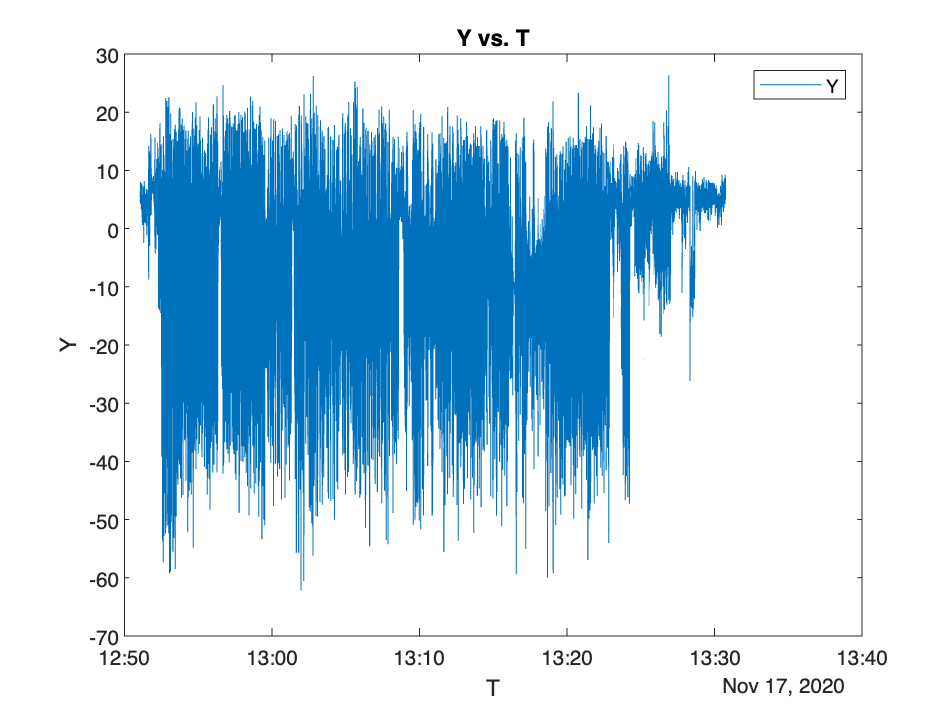

% Create plot of T and Acceleration.Y
h = plot(T,Acceleration.Y,"DisplayName","Y");

% Add xlabel, ylabel, title, and legend
xlabel("T")
ylabel("Y")
title("Y vs. T")
legend

## 3. Process Raw Acceleration Data

To convert the XYZ acceleration vectors at each point in time into scalar values, the magnitude is calculated. This allows large changes in overall acceleration, such as steps taken while walking, to be detected regardless of device orientation.

Thus $A = \sqrt{(A_x^2 + A_y^2 + A_z^2)}$

A_mag = sqrt(Ax.^2 + Ay.^2 + Az.^2);
A_mean = mean(A_mag)

A_mean = 14.3211

It is observed that the acceleration magnitude is not zero-mean. Subtracting the mean from the data will remove any constant effects, such as gravity.

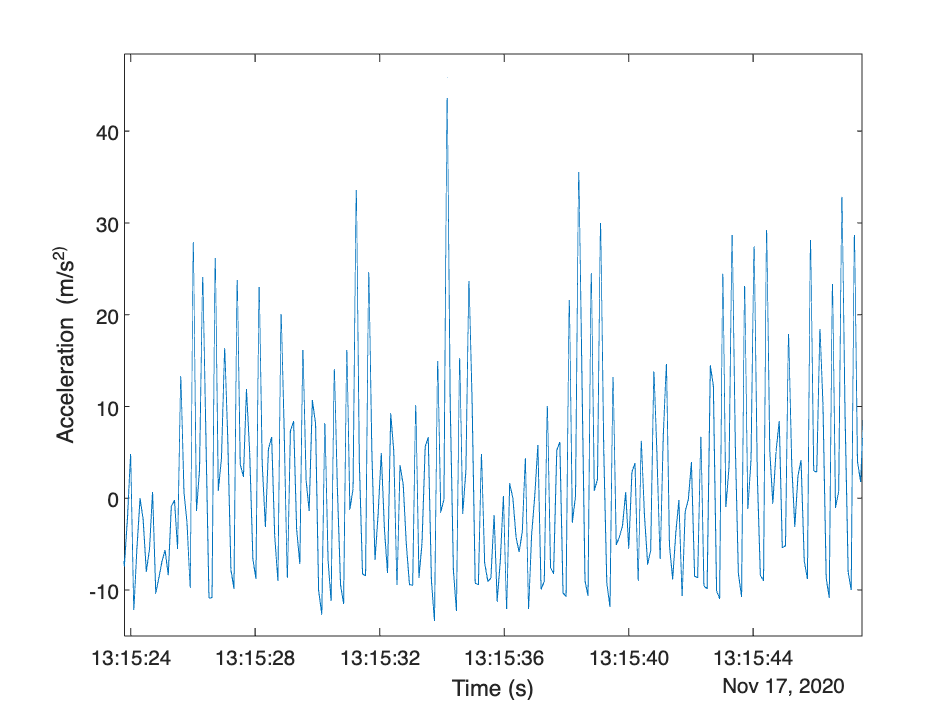

A_mag_z = A_mag - mean(A_mag);

plot(T,A_mag_z);
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

xlim([datetime(2020,11,17,13,15,23.8)...
      datetime(2020,11,17,13,15,47.5)])
ylim([-15.0 48.4])

The plotted data is now centered about zero, and clearly shows peaks in acceleration magnitude. Each peak corresponds to a step being taken while walking.

## 4. Count your Steps!

[findpeaks](https://www.mathworks.com/help/releases/R2020b/signal/ref/findpeaks.html) is a function from Signal Processing Toolbox that is used to find the local maxima of the acceleration magnitude data. Only peaks with a minimum height above one standard deviation are treated as a step. This threshold should be tuned experimentally to match a person's level of movement while walking, hardness of floor surfaces, etc.

minPeakHeight = 1.25 * std(A_mag_z);

[pks,locs] = findpeaks(A_mag_z,'MINPEAKHEIGHT',minPeakHeight);

The number of steps taken is simply the number of peaks found.

numSteps = numel(pks);
disp(['I walked ' num2str(numSteps) ' steps today.'])

I walked 2351 steps today.


The peak locations can be visualized with the acceleration magnitude data.

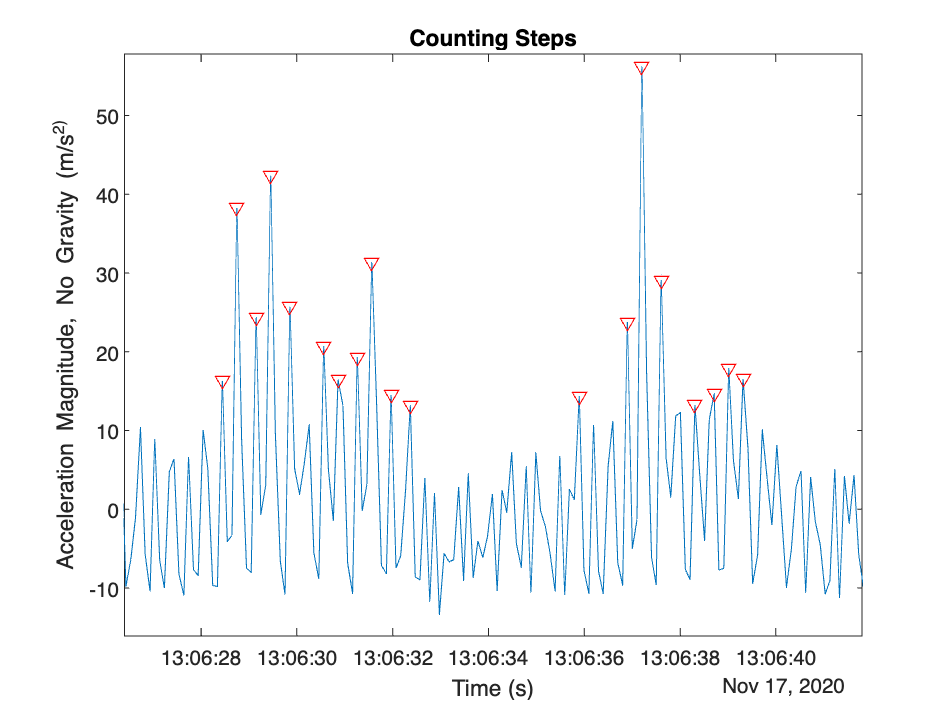

hold on;
plot(T(locs), pks, 'r', 'Marker', 'v', 'LineStyle', 'none');
title('Counting Steps');
xlabel('Time (s)');
ylabel('Acceleration Magnitude, No Gravity (m/s^2)');
xlim([datetime(2020,11,17,13,6,26.4)...
      datetime(2020,11,17,13,6,41.8)])
ylim([-16.1 57.8])
hold off;

## Calculate Total Distance for Run

Isolate variables from the Position vector.

% Enter you code here

lat = Position.latitude;
lon = Position.longitude;
positionDatetime = Position.Timestamp;
spd = Position.speed;

Use the [distance](https://www.mathworks.com/help/comm/ref/txsite.distance.html) function in MATLAB to calculate the distance between adjacent points based on position data.

earthCirc = 24901;
totalDist = 0;
totalspeed = 0;
mile1_spd = 0;
for i = 1: (length(lat)-1)
    lat1 = lat(i);     %The first latitude
    lat2 = lat(i+1);   %The second latitude
    lon1 = lon(i);
    lon2 = lon(i+1);
    diff = distance(lat1, lon1, lat2, lon2);
    dis = (diff/360)*earthCirc;
    totalDist = totalDist + dis;
    totalspeed = totalspeed + spd(i);
    if mod(totalDist, 1) == 0
        mile1_spd = totalspeed
    end


end

disp(['The total distance traveled is: ', num2str(totalDist),' miles'])

The total distance traveled is: 3.5353 miles


## Calculate Total Time taken for Run

The date-time datatype makes it very easy to calculate the time taken for the run. Simply subtract the last value from the first value in the Timestamp variable from the Position vector.

%Enter your code here

TotalTime = Position.Timestamp(end) - Position.Timestamp(1)

TotalTime = duration
   00:39:39


disp(['The total time taken to run the distance of ', num2str(totalDist) ,' miles is ', char(TotalTime)])

The total time taken to run the distance of 3.5353 miles is 00:39:39


## Pace Calculation

Pace is calculated in mins/mile. We know the total time and total distance covered, so calculating the pace should be a simple arithmetic operation.

%Enter your code here

pace = TotalTime/totalDist;
pace.Format = 'mm:ss'

pace = duration
   11:12


disp(['The average running pace in minutes/mile is: ', char(pace)])

The average running pace in minutes/mile is: 11:12


## Map Course

Let us visualize the course we ran. We will use a user-defined function as follows:

%Enter your code here

[s, nBins] = myPlotCourse(spd, lat, lon);

### Create a Web Map and Route Overlay

The pieces can now be combined into a webmap display. The latitude and longitude data have been processed to make up individual line segments to overlay on the map. Each line segment has a color corresponding to the speed recorded at the respective position. 

Mapping Toolbox provides a number of functions for working with web maps.

Use `webmap` to open a web map in a browser.

wm = webmap('Open Street Map');

A list of colors corresponding to the speed bins is generated using the `autumn` colormap. This creates an `[nBins x 3]` matrix with RGB values for each bin.

colors = cool(nBins);

A line is drawn on the webmap using the geographic shape vector. Each element of the shape vector corresponds to a discontinuous line segment for a binned speed value. These elements match the elements of the color list that was just created.

wmline(s, 'Color', colors, 'Width', 5);

Zoom the map in on the route.

wmzoom(15);
